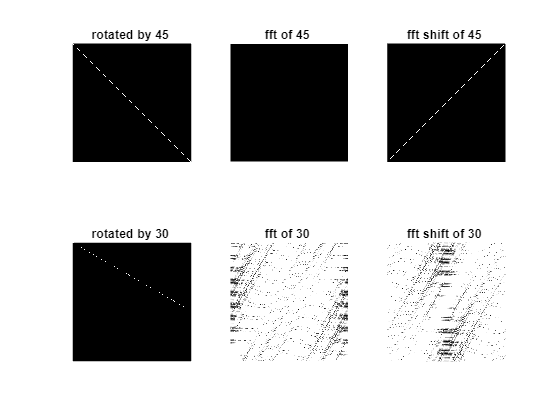

%rotating the lines by 45 degree
x=zeros(255,255);
for i=1:255
    for j=1:255
        if j==i
            x(i,j)=1;
        end
    end
end

fft_x=fft2(x);
fft_shift_x=fftshift(fft_x);
abs_fft_shift_x=abs(fft_shift_x);
abs_fft_x=abs(fft_x);

%rotating the lines by 30 degree
y=zeros(255,255);
for k=1:255
    for l=1:255
        if l==round(1.732*k)
            y(k,l)=1;
        end
    end
end

fft_y=fft2(y);
fft_shift_y=fftshift(fft_y);
abs_fft_shift_y=abs(fft_shift_y);
abs_fft_y=abs(fft_y);

subplot(2,3,1);imshow(x);title('rotated by 45 ');
subplot(2,3,2);imshow(abs_fft_x);title('fft of 45 ');
subplot(2,3,3);imshow(abs_fft_shift_x);title('fft shift of 45 ');
subplot(2,3,4);imshow(y);title('rotated by 30 ');
subplot(2,3,5);imshow(abs_fft_y);title('fft of 30 ');
subplot(2,3,6);imshow(abs_fft_shift_y);title('fft shift of 30 ');